clear;
close all;
clc;

## Load the raw data

load('bp.mat');

## Plot the raw time signal

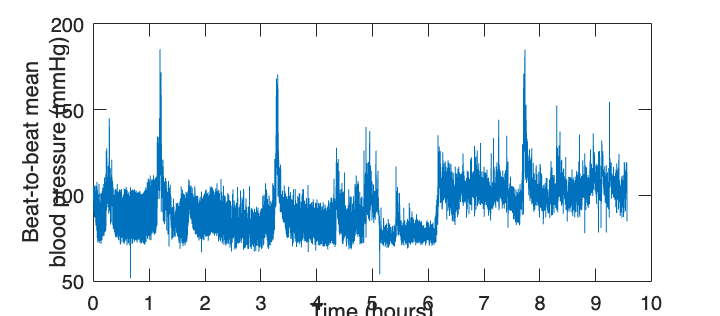

fs = 20;
t = (0:length(bp)-1)'/fs;
figure('Units','centimeters','Position',[0,0,25,11],'Color','w');
plot(t/3600, bp);
xlabel('Time (hours)');
ylabel({'Beat-to-beat mean','blood pressure (mmHg)'});

## Baseline attenuation: Highpass filter on the BP signal

The lower limit of the LF range is 0.04 Hz. With a cut-off frequency at 0.01 Hz, one can check (with the freqz function for instance) that we do not attenuate significantly any frequency component >= 0.04 Hz. Therefore, 0.01 Hz is a good trade-off between effective baseline cancellation and preservation of the frequency bands of interest.

[b,a] = butter(2, 0.01/(fs/2), 'high');
bp = filtfilt(b, a, bp);

## Spectrogram of the BP signal

Adjust the window duration below to a better value and explain your choice.

winduration = 1;    % Window duration in seconds: Find a better suited value
window = round(winduration*fs);
noverlap = round(0.95*winduration*fs);  % Overlap of 95%

figure('Units','centimeters','Position',[0,0,30,11],'Color','w');
spectrogram(bp, window, noverlap, [], fs, 'yaxis');
ylim([0,0.4]);
colormap('jet');
title('Spectrogram of the beat-to-beat mean BP signal');

% Adjust the lower limit of the colormap to a better value to improve the
% readability of the spectrogram.
cmaplowlim = min(get(gca, 'clim')); % Lower colormap limit: Find a better value
set(gca, 'clim', [cmaplowlim, max(get(gca, 'clim'))]);